# Homework # 8: Due 11:59pm, Tuesday, April 27

Ver. 9

April 21, 2021

**Please Note:** You are encouraged to watch our first lecture video on "probability concepts" before starting on Problem 2 in this homework.

## Problem 1: Stiff ODE (20 points)

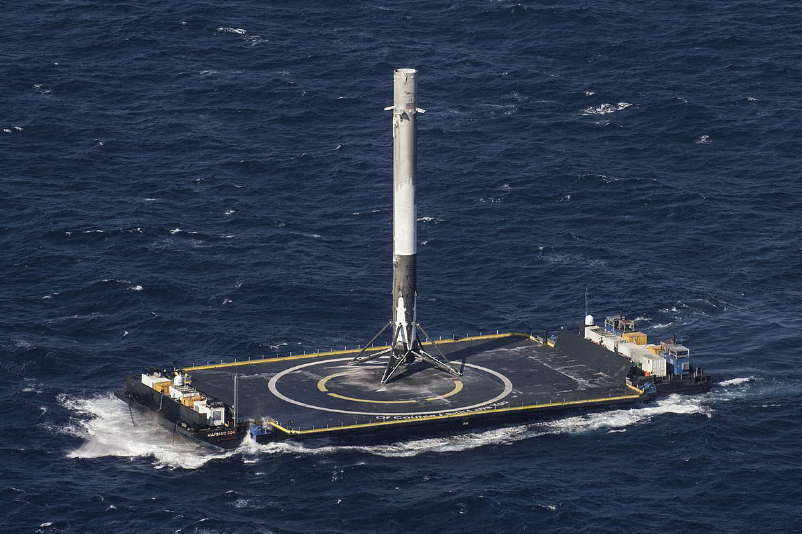

Consider vertical vibrations of the SpaceX droneship *Of Course I Still Love You*, during the event of a rocket landing. A lumped model describing the coupled dynamics is:

where $y_b$ represents the vertical location of the barge, and $y_r$ the vertical location of the rocket, so that $y_b -y_r$ is the compression of the rocket's suspension system once contact has been made at time *t* = 0. The barge is at equilibrium before the landing, so $y_b \left(0\right)=\dot{y_b } \left(0\right)=0$, while $y_r \left(0\right)=0$ and $\dot{y_r } \left(0\right)=-1$m/s.

a) (5 points) The system can be represented in state-space form as $\dot{x} =Ax$, with $x={\left\lbrack y_b ,\dot{y_b } ,y_r ,\dot{y_r } \right\rbrack }^T$ being the state vector. Derive the numerical expression for matrix *A*, i.e., a 4x4 array of numbers.

clear; close all; clc;

% Put your numerical A matrix here:
%
A = [0, 1, 0, 0;
    -400.6, -1, 400, 0;
    0, 0, 0, 1;
    4000, 0, -4000, -12;]

A = 	1.0e+03 *

         0    0.0010         0         0
   -0.4006   -0.0010    0.4000         0
         0         0         0    0.0010
    4.0000         0   -4.0000   -0.0120


b) (7 points) Use ode45 to solve for the position of the barge over the interval $0\le t\le 10$seconds.

% Put your code here:
dxdt = @(t,x) A*x;
initials = [0; 0; 0; -1;];
[tout, xout] = ode45(dxdt,[0 10],initials);
barge_position = xout(1,:);

c) (8 points) The "Crank-Nicolson" method is given by

Use this scheme to solve for the position of the barge  over the interval $0\le t\le 10$seconds using a time step of 0.01 seconds.

% Put your code here:
dt = 0.01;
t = 0:dt:10;
x = initials;
x2=zeros(4,length(t));
x2(:,1) = initials;
for j=1:length(t)-1 % Loop through all the times (except the first one)
    fz = @(xnew) xnew-x2(:,j)-(dt/2)*dxdt(t(j),x2(:,j))-(dt/2)*dxdt(t(j+1),xnew);
    x2(:,j+1) = fsolve(fz,x2(:,j));
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

I = eye(4);
for i=2:length(t) % Loop through all the times (except the first one)
    x_recent=x(:,end);
    x_new=(I-0.5*A*dt)\(I+0.5*A*dt)*x_recent; % Apply the marching formula
    x=[x x_new];
end

## Problem 2 (20 points) 

Suppose we are given a six-sided die such that even numbers are *five times* as likely to come up as the odd numbers and all the odd numbers are equally probable and all the even numbers are equally probable.

a) (5 points) Let `X` denote the number that comes up at each throw. What is the probability of `X` for `X=1,2,3,4,5,` and `6`?   Recall that in the lecture on "probability concepts" that the sum of the probabilities over all possibilities must be one.  Store the probability of each outcome in the corresponding location in a vector named p.

clear; close all; clc;

% Put your code here:
%
p = [1/18, 5/18, 1/18, 5/18, 1/18, 5/18];

b) (2 points) Make a bar graph of the probability with the x axis representing values 1 through 6 and the y axis representing the associated probabilities from part (a).

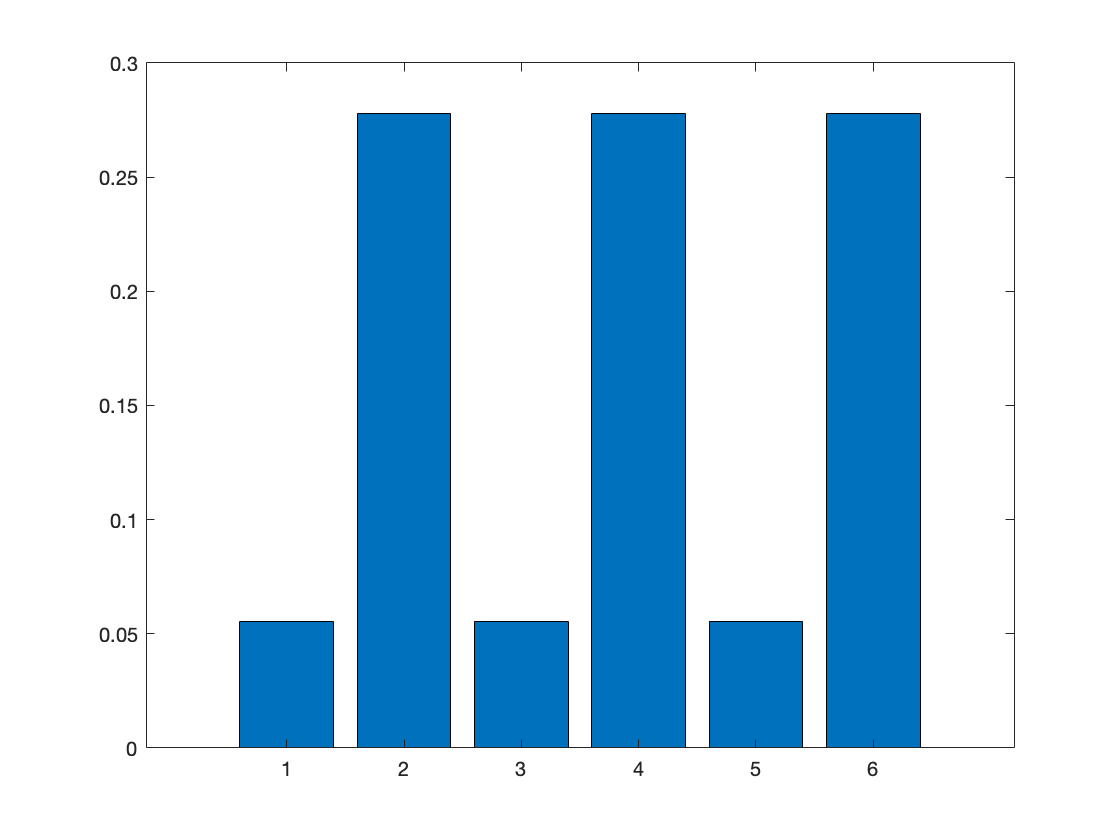

% Put your code here:
%
bar(1:6,p)

c) (2 points) Use the probabilities from part (a) to compute the expected value of `X and place the answer in a variable named mu_X.` Next week's lecture will explain that the expected value for a set of six discrete numerical outcomes is $E\left(X\right)=\sum_{l=1}^6 x_l \cdot P\left(x_l \right)$ 

% Put your code here: 
%
mu_X = 0;
for i = 1:6
    mu_X = mu_X + i*p(i);
end
mu_X

mu_X = 3.8333

d) (2 points) Use the probabilities from part (a) and the expected value from part (c) to compute the variance of `X and place the answer in a variable named sigma2_X.` Next week's lecture will explain that the variance for a set of six discrete numerical outcomes is $\sigma_X^2 = \sum_{\ell = 1}^6 \textrm {P}(x_\ell) (x_\ell  - \mu_X)^2\; .$

% Put your code here: 
sigma2_X = 0;
for i = 1:6
    sigma2_X = sigma2_X + p(i)*(i-mu_X)^2;
end
sigma2_X

sigma2_X = 2.8056

e) (4 points) The starter code below generates a million realizations of a random variable distributed as specified the previous parts of this problem.  Use the results to check on your solution to parts (c) and (d). 

n=10^6;
r=rand(1,n);
d=1*(r<1/18)+2*((r>=1/18)&(r<1/3))+...
  3*((r>=1/3)&(r<7/18))+4*((r>=7/18)&(r<2/3))+...
  5*((r>=2/3)&(r<13/18))+6*(r>=13/18);

% Put your code here: 
% 
mean(d)

ans = 3.8326

var(d)

ans = 2.8073

% the mean and variance found from the sample is close to the expected
% value and variance; thus I believe my answer to c and d are correct.

f) (5 points) What is the probability of rolling a 7 with a pair of these dice?  You can use any method you prefer, but show your work clearly.  Save your result in variable `p_7`. 

% Put your code here: 
% the probability of rolling a 7 with a pair of these dice are:
% 2*(P(1)*P(6)+P(2)*P(5)+P(3)*P(4)) because e.g. roll 2 first then 5, roll 5 first then 2
p_7 = 2*(p(1)*p(6)+p(2)*p(5)+p(3)*p(4))

p_7 = 0.0926

## Problem 3 (15 points) 

Let's say that the departure of a plane in each time unit of $1/n$ hour from a particular airfield can be modeled as a Bernoulli distribution with parameter $\theta$. For $n$ an integer, let  the number of aircraft departures in any given hour be a random variable $K$, taking any (integer) value between 0 and $n$, inclusive. The probability of exactly $k$ flights in an hour can be described by the binomial pmf 


$$p_K^{\text{binomial};\theta,n}(k) = {n\choose k}(1-\theta)^{n-k}\theta^k$$


a) (4 points) Write a function named` p_binom` (template can be found at the end of this script) that takes  `n`, `k` and `theta` as input parameters and outputs the binomial pmf evaluated at the specified ` k` values.  Your function should work correctly for both scalar and vector `k` inputs. Use the function header provided in the MATLAB script associated with this homework. When building your function you may assume that 0 $\leq$`n`$\leq 25$.

b) (3 points) Provide a bar graph of the probability distribution of number of flights if $\theta= 0.4$ and $n= 12$ using your `p_binom` function from part (a).

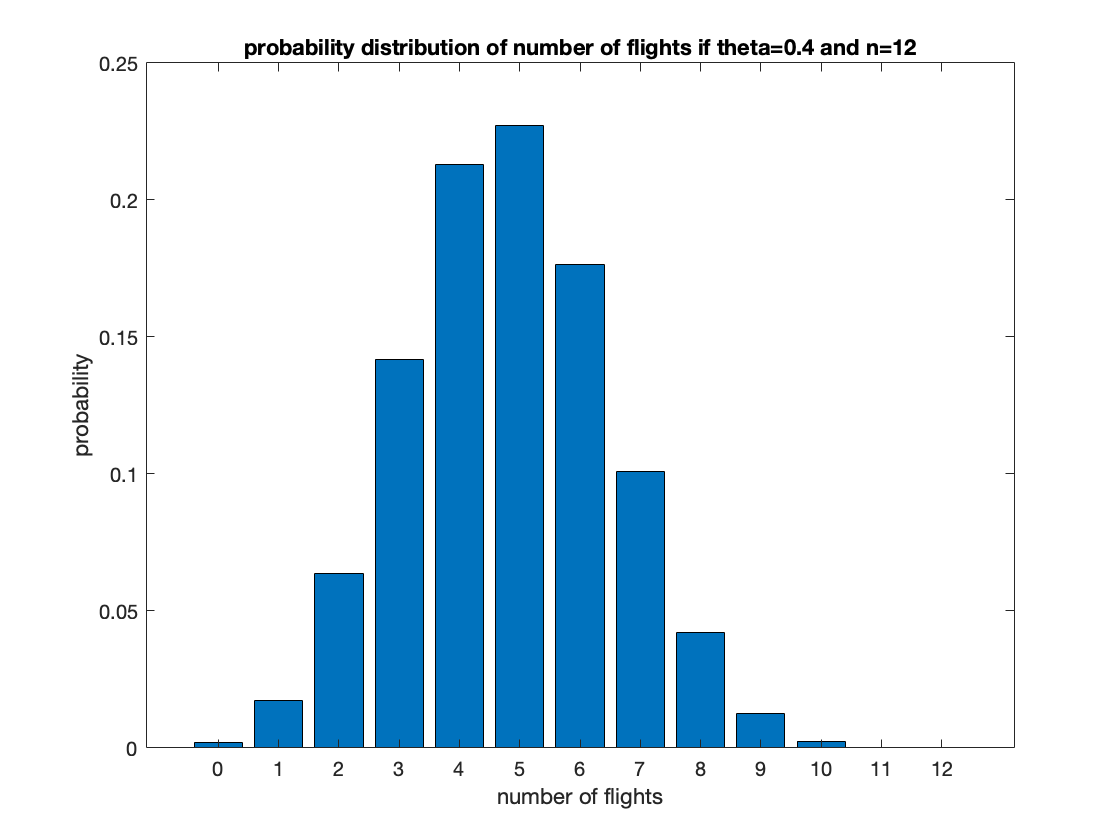

clear; close all; clc;

theta=0.4;
n=12;

% Put your code here:  
%
k = 0:n;
f_x = p_binom(n,k,theta);
bar(k,f_x)
xlabel("number of flights")
ylabel("probability")
title("probability distribution of number of flights if theta=0.4 and n=12")

c) (4 points) Calculate the expected value and standard deviation of the number of flights departing in an hour, if $\theta= 0.4$ and $n= 12$.

% Put your code here:  
%
mu=sum(f_x.*k)

mu = 4.8000

sig2=sum(f_x.*(k-mu).^2)

sig2 = 2.8800

d) (4 points) Determine the probability that there will be 4 or fewer flights departing in an hour for $\theta=0.4$ and $n= 12$.

% Put your code here and call the probability air_p 
%
air_p = 0;
for i = k
    if i<=4
        air_p = air_p + f_x(i+1);
    end
end
air_p2 = sum(f_x(1:5));
air_p

air_p = 0.4382

## Problem 4 (25 points)

Consider two different functions


$$f_x \left(x\right)=\left\lbrace \begin{array}{ll}
\frac{1}{2} & 0\le x\le 2\\
0 & \textrm{otherwise}
\end{array}\right.$$



$$f_y \left(y\right)=\left\lbrace \begin{array}{ll}
\frac{1}{3} & 0\le y\le 3\\
0 & \textrm{otherwise}
\end{array}\right.$$


these happen to represent the probability density functions of two independent random variables, but you don't need to concern yourself about that yet.  This is just a chance to practice integration.  The convolution integral is defined as

NOTE: For efficient computation, it is better to replace the limits above with ones that cover the values of psi where the integrand is not zero and not much more than that.

a) (10 points) Use the trapezoid rule with step size 0.01 to compute $f_z \left(4\right)$ and place the result in a variable called fz4.

clear; close all; clc;

% Put your code here: 
%
z = 4;
step_size = 0.01;
zeta_range = -1:step_size:4;
f_x = @(x) (0<=x & x<=2)*1/2;
f_y = @(y) (0<=y & y<=3)*1/3;
fz_4 = @(zeta) f_y(4-zeta).*f_x(zeta);
z_values = fz_4(zeta_range);
fz4 = trapz(zeta_range,z_values)

fz4 = 0.1683

b) (12 points) Compute and plot $f_z \left(z\right)$ for values over the range $0\le z\le 5$.  You probably need about 100 values to show the plot clearly enough.

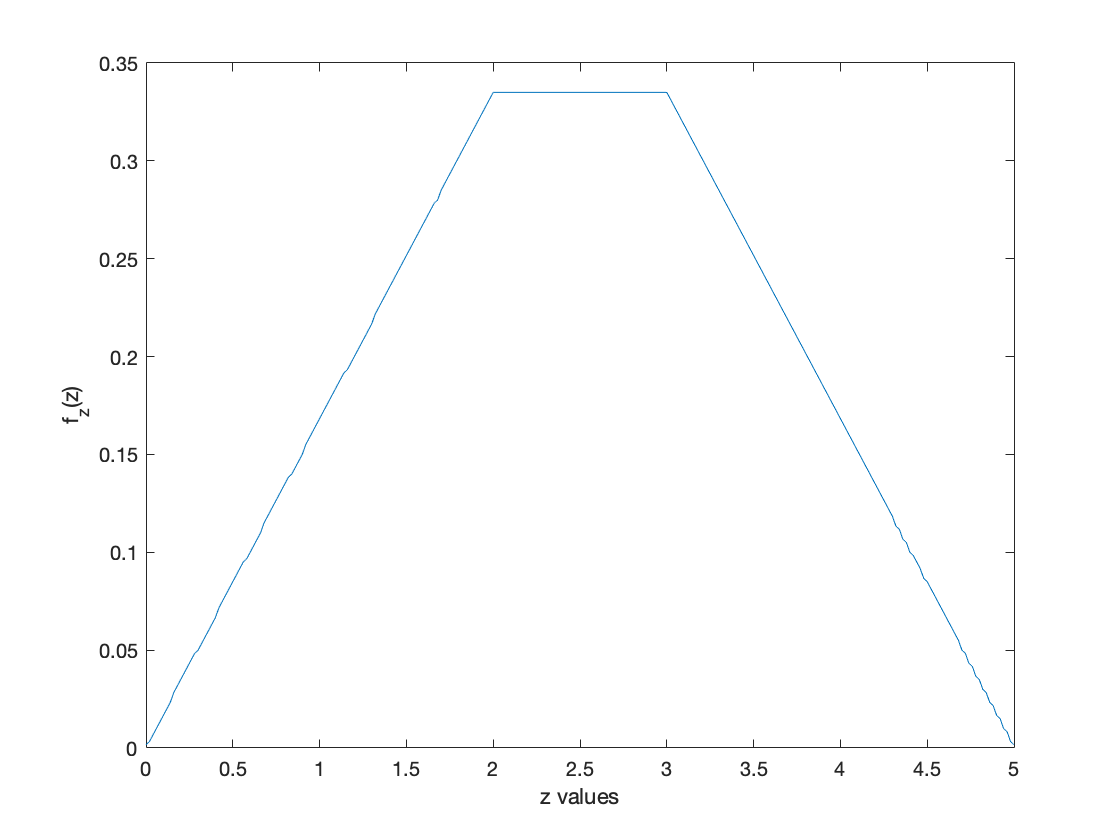

% Put your code here: 
%
f_z = @(z, zeta) f_y(z-zeta).*f_x(zeta);
z_range = 0:0.02:5;
fz = ones(1,length(z_range));
for i = 1:length(z_range)
    fz(i) = trapz(zeta_range,f_z(z_range(i),zeta_range));
end
plot(z_range,fz)
xlabel("z values")
ylabel("f_z(z)")

c) (3 points) A simulation of the random process is often a useful means to confirm a result.  Generate 10^6 random variates from $f_x \left(x\right)$ and $f_y \left(y\right)$.  Add each corresponding element to form instances of random variable $Z$.  Plot a histogram so that you can compare that graph to the result from part (b).

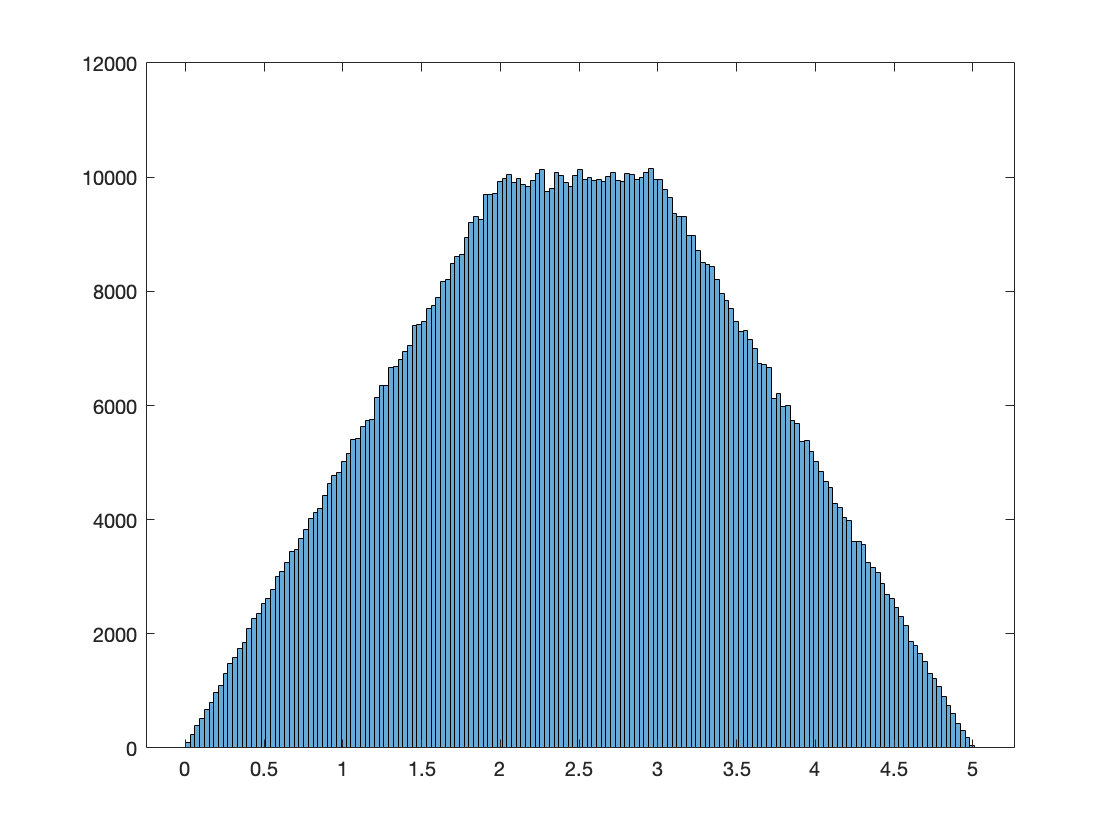

% Put your code here: 
%
n = 10^6;
xvals = 2*rand(1,n);
yvals = 3*rand(1,n);
zvals = xvals+yvals;
histogram(zvals)

## Problem 5: Wire Structures and Sculptures (20 points)

It would be interesting to make structures and sculptures out of single pieces of steel wire.  How elaborate could they be and still be manufacturable?  Here is some geometry to test the limits.  Below is a photo of a stone artifact which depicts Quetzalcoatl, the feathered serpent deity from Aztec culture which is at the Ciudadela complex in Teotihuacan.

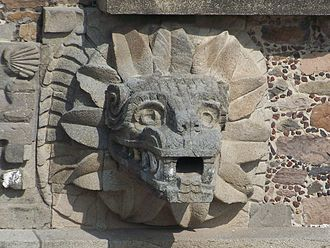  

I was able to find a casting made from this artifact.  I digitized the casting with a 3D laser scanner.  With some preprocessing, I was able to make a single strand that, to me, was a reasonable facsimile of Quetzalcoatl.  The structure is represented as a list of 928 consecutive locations in 3D space (measured in millimeters).  The code below makes a plot of the wire sculpture.

clear; close all; clc;

[X,Y,Z]=quetzy(); % Let's say these are in centimeters
plot3(X,Y,Z,'k-')
axis equal 
axis off

a) (3 points) Compute the total length of wire needed to make the sculpture.  You can assume there is a straight line between every X,Y, Z location the subsequent one.  You can also assume that the change in angle at each vertex is instantaneous so that the sculpture is an assembly of line segments.  Store the result in a variable named "length_of_wire".

% Put your code here: 
%
length_of_wire = 0;
for i = 1:length(X)-1
    length_of_wire = length_of_wire + norm([X(i) Y(i) Z(i)]-[X(i+1) Y(i+1) Z(i+1)]);
end
length_of_wire

length_of_wire = 7.7106e+03

b) (2 points) What is the order of operations for the computation in part (a)?  Consider n to be the number of X,Y, Z locations in the sculpture.  Express your answer in "big O" notation.

% Put your comment here:
% 
% it would be O(n) since the sum of lengths between points is calculated by
% calculating the distance between each n points.

c) (10 points) This structure might be overly compliant unless we take some steps to stiffen it.  Let's say that we want to spot weld the wire to itself in 24 strategically located positions where the wire comes close to intersecting itself and does so in a favorable way.  Find 24 pairs of vertices (X,Y, Z locations) that are the most closely spaced pairs to each other ("close" being defined using the Euclidean distance in 3D space, aka the "two norm").   Exclude any vertex pairs in which the length of wire between them is not at least 1% of the total wire length computed in part (a).  Store the 24 strategically located pairs in a 24x2 matrix called WeldPairs with one column being the index of a vertex and the other column being the matching vertex to which the weld is proposed to be made.

% Put your code here: 
%
WeldPairs = ones(24,2);
lengths = Inf(1,24);
for i = 1:length(X)
    for j = 1:length(X)
        if i~=j
            len = norm([X(i) Y(i) Z(i)]-[X(j) Y(j) Z(j)]);
            if len<max(lengths)
                max_index = find(lengths==max(lengths), 1);
                WeldPairs(max_index,:) = [i j]';
                lengths(max_index) = len;
            end
        end
        
    end
end
WeldPairs

WeldPairs =    440   488
   493   475
   284   818
   475   493
   140   858
   485   439
    99    95
   237   232
   488   440
   818   284


d) (2 points) What is the order of operations for the computation in part (c)?  Consider n to be the number of X,Y, Z locations in the sculpture.  Express your answer in "big O" notation.

% Put your comment here:
% 
% O(n)=n^2, the two for loops going through 1 to n and 1 to n yields a
% total of n^2 opearations

e) (3 points) Plot the locations of the 24 WeldPairs (as red circles and a connecting line) along with the wire structure (as a black line).

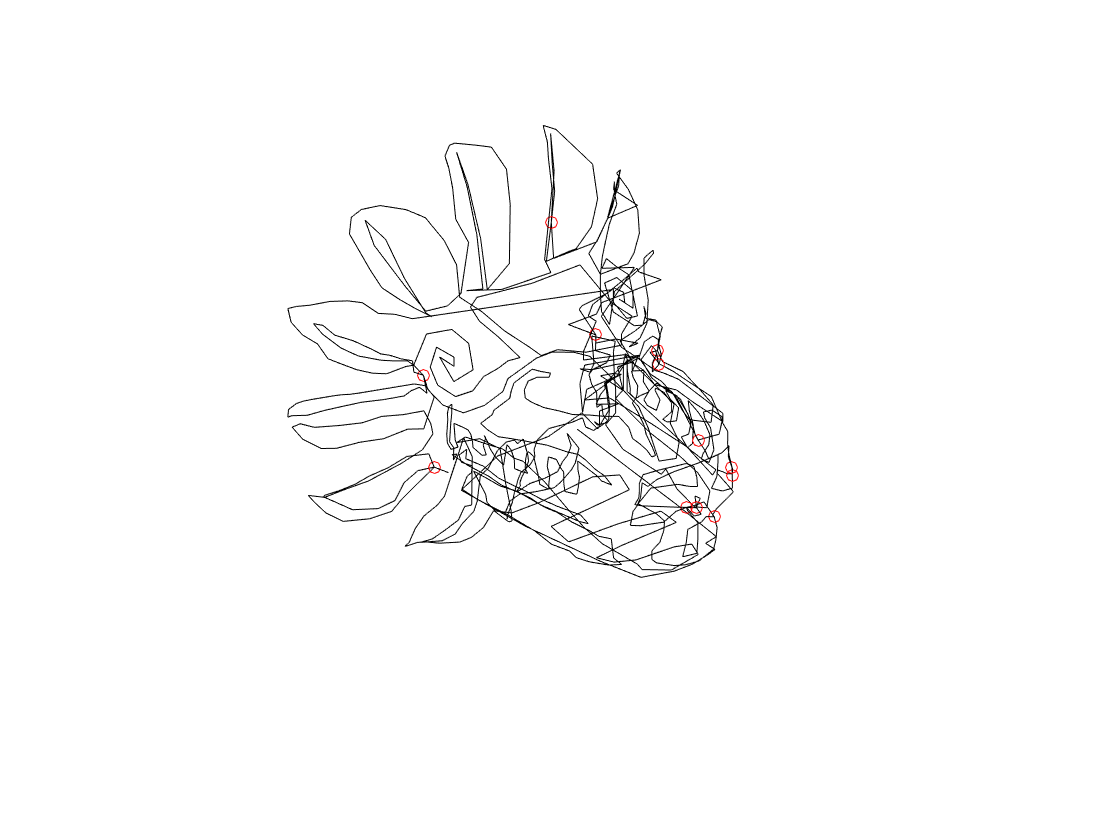

a =    94.6297    6.1293  104.8121


b =    94.6297    6.1293  104.8121


a =    99.5490    1.5452  101.2391


b =    99.5490    1.5453  101.2391


a =   135.6670  122.4953  112.9320


b =   135.6670  122.4952  112.9320


a =    99.5490    1.5453  101.2391


b =    99.5490    1.5452  101.2391


a =    53.0627  122.5606  124.2492


b =    53.0627  122.5607  124.2492


a =    90.9357    7.6528  105.5777


b =    90.9357    7.6528  105.5777


a =   115.7762   57.3124  136.7302


b =   115.7762   57.3124  136.7302


a =   115.4790  124.0315  168.7798


b =   115.4790  124.0315  168.7798


a =    94.6297    6.1293  104.8121


b =    94.6297    6.1293  104.8121


a =   135.6670  122.4952  112.9320


b =   135.6670  122.4953  112.9320


a =   130.8255   77.7051  128.2268


b =   130.8255   77.7051  128.2268


a =   102.8265   15.8798  127.2024


b =   102.8265   15.8798  127.2024


a =    55.8642  119.4904   84.3352


b =    55.8642  119.4904   84.3352


a =   118.0239   14.5534  110.5484


b =   118.0239   14.5535  110.5484


a =    55.8642  119.4904   84.3352


b =    55.8642  119.4904   84.3352


a =   118.0239   14.5535  110.5484


b =   118.0239   14.5534  110.5484


a =   102.8265   15.8798  127.2024


b =   102.8265   15.8798  127.2024


a =   115.4790  124.0315  168.7798


b =   115.4790  124.0315  168.7798


a =   130.8255   77.7051  128.2268


b =   130.8255   77.7051  128.2268


a =   115.7762   57.3124  136.7302


b =   115.7762   57.3124  136.7302


a =   118.0319   14.3319  107.1592


b =   118.0319   14.3319  107.1593


a =   118.0319   14.3319  107.1593


b =   118.0319   14.3319  107.1592


a =    53.0627  122.5607  124.2492


b =    53.0627  122.5606  124.2492


a =    90.9357    7.6528  105.5777


b =    90.9357    7.6528  105.5777


% Put your code here: 
%
hold on
for i = 1:24
    ind1 = WeldPairs(i,1);
    ind2 = WeldPairs(i,2);
    plot3(X(ind1), Y(ind1), Z(ind1),'ro')
    plot3(X(ind2), Y(ind2), Z(ind2),'ro')
    plot3([X(ind1) X(ind2)],[Y(ind1) Y(ind2)],[Z(ind1) Z(ind2)],'k-')
end

Function Definition for Problem 3:

function p=p_binom(n,k,theta)
% Put your code here:
%
    p = binopdf(k,n,theta);
end


Function Definition for Problem 5:

function [X,Y,Z]=quetzy()
X=[124.167090510808
117.565278641374
114.366123070272
108.678226893488
108.678230556761
101.134829838989
93.6042522652641
84.8228004043568
74.5433336449014
67.0440632599676
63.7338271443152
62.2576404536236
85.6197729713270
110.046003223600
129.203879519736
140.706265732083
155.961273684728
162.765407092922
168.226766496814
168.296930265490
158.258813869782
131.673030929310
132.439910882613
129.652322615529
135.740862411108
165.453476424096
131.627797280975
129.505790852819
130.171916574747
130.171975530555
125.064957450687
125.809475723758
127.232477935758
129.835179008773
133.563472362492
133.563479562907
133.563463614493
129.105079222759
126.665333435425
123.488827244885
123.488811664263
123.488834787072
124.927290308644
128.170515472351
129.181747269292
131.753833532343
133.451630853424
133.451698724644
133.494328914691
151.016151437361
134.330799531668
133.516227122946
131.527945033080
131.528013227354
128.634465574704
131.375690376441
132.310439476814
132.971611485694
132.971585205187
132.640493556909
132.309355117917
133.456292979330
133.456356190651
133.456335201748
133.302264597409
133.755340588315
133.806160604061
133.806102375114
130.175271070981
127.187803869612
120.639833961943
115.679306950586
121.964130686604
127.717434214884
130.825545663732
130.458079071462
126.775968371960
123.655305841721
122.267497975425
122.267517957704
116.784240595238
113.069564044825
102.826455180134
101.989071322411
101.983628249297
100.033754937654
101.180610039457
101.180613732087
102.434956899516
108.589138059141
115.034075312683
120.416731517725
120.903218216485
120.872832076895
115.776174043435
109.246293504911
109.246293059749
114.966727801517
115.776196729502
116.192753322805
112.964881556784
104.963976845977
106.481399350958
105.446000755773
105.446078774010
103.221781610683
111.852876785888
116.825899789056
116.895749432603
119.748034657674
122.598580276595
126.183491891522
130.825494180123
127.906178554778
126.001008025155
121.455610623408
116.041431676412
106.721806690029
97.7184296257320
96.5391891068354
97.0137922576967
97.3196163909651
94.1171497602831
93.8875751752884
90.9255391290725
83.5360665728149
84.1697134756680
84.1764622249962
84.2304071616914
83.0001307122914
79.2173461029369
71.6288893888573
64.2062213624087
58.3276590171970
58.9978944649288
56.0182359379283
53.8913142590851
52.9087441642615
51.7215784086811
53.0626848102121
48.1263518696759
54.2007937592403
56.8683679546065
57.9587845391389
56.4407886549588
53.4908336025796
54.0911718886283
54.0911728629270
54.0912124681683
53.6768416707098
52.0763688779991
52.5800978293203
52.7220567944426
54.6214914110768
56.3712578053463
58.9715046639655
61.1553588422232
64.8277600230469
65.2677164116003
64.0209652883674
66.5875598649529
74.2554050897453
95.9575697126833
118.931476635400
111.003515206469
111.003480889102
102.015979955478
97.4147310175636
83.0079565328752
74.1630617146120
67.8204739126273
66.5695067101697
66.5694631927323
67.8617431926478
67.8617381859033
65.4808902119561
64.3105985706877
59.4101014984553
54.4395507531593
48.1617091965152
43.0635930685114
39.2092733336476
34.1094586457237
33.8706522425143
36.2193503646832
42.4255477806638
48.6859788389388
56.2576580068089
56.2576744472222
51.3715042345115
47.8688320526573
42.9795140060433
42.7846667506011
50.0602664364897
56.2635460047705
62.7221574271223
69.1566252860067
70.6012974821621
70.6572781796755
74.4727699662969
76.9962806772000
78.2567968842129
84.4888687253699
86.9829595952071
94.4381075545700
97.5834105258595
99.0217753695703
96.3613800904223
93.7892278999560
84.5282447701639
87.0523673222450
88.2690162459972
86.9855673170850
87.0091862821980
85.7794011600966
81.9561757564720
71.7158319261366
90.9605286919129
108.810613857725
108.768293830006
116.555901835925
120.054704855778
124.503582874367
129.405866493027
135.651719544867
141.813767085845
138.142815538023
132.760407893743
124.796412380109
120.484495560124
110.081583943017
115.479029946477
121.640262387809
125.191174415651
132.127215823018
125.427966573785
115.479011858745
112.914697587980
122.505887943981
133.588622478297
144.308035286530
148.418777379213
159.901052144384
141.848260850104
148.015631375538
154.524363680883
161.981916617424
164.835522170657
167.571930778450
166.299911343717
161.434488557586
154.792174073522
149.503422579029
136.243134603790
140.882007806874
145.973436310406
151.327529470919
158.725389350367
160.180162769418
160.180144234519
155.112137391612
155.112156834364
144.307995148044
136.639646382665
132.040748828175
136.243193843963
136.243200218718
136.243193763175
134.375538208045
134.914747496524
144.623537467186
163.676783705141
172.166268250771
175.861015249744
177.355388670982
177.355458886833
175.135318060037
166.891099406324
159.732174983845
152.607431218804
154.251378491433
144.524867262247
135.666995937211
135.667030115677
128.004074149958
142.217836077164
148.903062837267
163.873991902940
177.415970414914
174.677718224101
173.317498500410
161.522071835146
143.990089409723
137.649013320728
137.649102716918
129.545431748017
129.545458375395
148.573145148725
152.851487925973
159.199107339162
164.741370567409
168.336070896764
168.333578834571
165.453560125123
161.518673953410
156.987138908966
151.891940257531
146.894003833329
139.801954980102
137.868624290286
137.868619255645
137.868611584581
146.893973054825
143.117140656119
148.752724749887
155.259241847491
159.039390852529
164.236330216777
156.628572399943
147.656961492396
147.656972336296
147.656957085659
150.371194612356
158.124655518166
161.957686207203
164.486319947844
167.005040453587
167.005056670857
165.197235994306
158.124644179390
148.663356199961
137.776772304676
129.956133601872
128.815027876819
128.554860101617
128.453584738123
133.041800269691
131.564834213911
132.030496778144
132.537407275183
132.537430249788
132.537481600149
128.152367633451
124.888358277510
124.888336031288
124.888338648163
124.591118351546
121.540034860251
119.994105404151
120.495104479627
122.474888058921
124.386343292572
126.572972576245
128.365645249470
132.537483301640
134.604864894155
134.604876875107
134.604783090776
134.428638600995
133.563401957798
131.106289061605
130.642330358702
132.186210149930
132.616983532608
129.915791793280
130.123881506478
130.025140368114
131.060300015519
133.563465229958
129.737216549792
131.106702147453
130.839974878277
130.589659351098
129.805549262111
130.350498298876
129.239829884988
127.841904640068
128.454737246651
129.765652374235
129.765650794837
128.614944159903
128.984899681818
128.984899916375
128.419367197175
128.350888900881
125.974166656715
125.855561656895
126.782768642559
127.012125301216
127.295224897016
127.315663572172
127.823026194036
126.134805341394
125.535421386812
124.976783662181
125.037382314972
125.394765626035
124.362729423262
124.884179236533
125.561962166557
125.984818058973
125.499976765352
126.487312352650
124.459264068118
124.506547706737
124.956224399587
125.102890466758
124.015144791061
122.156016696467
122.933719904664
122.933660877825
120.553745572094
119.262508264441
118.026307257743
118.029980965087
118.022890943794
118.023923127482
118.031883399948
118.039573037537
118.039552932473
113.103866580251
107.334404914964
109.381094201496
110.609554551354
110.609546369753
100.674081793965
89.3137227577131
81.6099501310953
77.7530303120988
77.7529655129380
74.8430039485440
72.9731732715432
72.3095417319898
69.8401761232627
73.5774816063237
76.0943382485496
79.8686027672367
86.0200910433701
90.9356597073432
94.6296895524193
99.5195953600378
98.3049965529781
94.6337739111985
90.9357058565443
87.2467036796586
80.8605921299040
78.3583910331466
79.6303345751871
79.6477397430770
79.6477005340108
82.1417464337575
88.3601148515915
100.746258142513
104.460084593722
105.700682603956
105.701837619323
101.981618985219
97.0222279539630
84.6214112493658
79.6098415015169
81.0054630493973
81.0800987015575
79.9489586515678
77.3875939743545
75.1856689397227
75.1857170084725
77.7302748905810
82.3011110753409
87.2271360055239
92.1643285282348
99.5368224708438
101.992251027216
100.768021714829
100.770998124259
99.5489596860443
95.8764263838505
93.4299467067083
87.2957172124186
86.0614298360237
86.0079442586318
90.9501776028230
90.9729345931935
90.9729600012201
90.9392890156398
90.9356980645068
92.1838764484883
94.6445103595009
94.6296650131766
94.6338402625633
97.0850749862122
98.3087406015576
99.5394510958238
99.5489611307454
100.767945581575
104.450479704530
110.607857897794
114.323063780388
119.304302154897
121.875335486756
125.140281244869
125.805036204913
123.217769114797
121.226631096984
119.286463092236
118.021312180421
118.023943659537
118.031868564299
118.023932122645
118.037276771238
117.255401545284
112.159272704270
105.328646916760
103.994426741101
102.826457674459
102.184249034570
103.221769291274
101.986040942863
100.958456631188
97.5103951577765
92.0444942412112
88.3223691870679
85.4526804490898
82.9163528703284
82.9080392724216
82.8999814399945
82.9002914761982
82.8962540352557
82.8921901828456
82.8893564949471
81.0431998599814
81.0212265966538
79.7583783960713
78.4733179081184
79.6574011326321
79.1198294458769
75.3075416845637
71.4893170097902
67.6560982645896
66.1692321545032
64.7105514755365
63.6387754674704
62.3845720357643
61.8418317296777
63.0569657960064
66.0295083448170
68.2748363790961
69.4622449041218
70.4348158827456
67.0721433961044
66.1110640824959
65.5826066233560
63.6346168661893
63.1669379388302
60.7747752015683
60.2195232596582
60.5549196013868
58.0888972994978
57.1924573417170
57.2930526438446
56.8215269934620
55.2470496283602
54.2647216993272
54.2646974253567
55.5318038994078
56.0391016831800
56.5630422417995
57.6667016046704
60.0972907705396
60.8639218599014
61.7323386128806
61.6177499195581
63.8434502022214
65.7107615548591
63.3116424451816
63.0538109857579
62.2497964120511
61.7236369223357
61.7336072514138
61.3412400606390
60.5038136419274
60.8163946048674
61.5187342930515
59.9448113045045
60.5982889506382
60.6466757583564
58.8662698337340
58.9407041014306
58.2356062795104
59.1900907096117
57.0231802198756
57.2134973299283
57.8537544819116
58.9480526484556
57.3712227630049
57.9695646515000
56.2101359964055
57.8467181434637
57.1931922202148
57.5639863773184
56.6413788456171
56.3076469292980
59.1114338526773
58.1767150536421
57.5076631869221
57.4764989212081
56.9932347815894
57.0497608115499
57.8627797467280
56.6780548799262
57.2568900345381
56.0416644935295
55.5895636457272
55.4099132727458
54.6310601050897
58.3361333977663
56.5651525926928
57.0954207588759
57.0629203069539
55.4066832238630
55.2466543689348
55.5135414024526
55.3092634119833
53.7824140249233
53.2148269824255
54.3698560622272
53.6422374693697
55.3401146171119
53.5681717800396
52.7009862479268
52.3561392417430
53.2255610264285
53.0234314370216
56.8115292133113
60.0501156924017
59.8845028970121
59.1276388411725
56.7872266888806
59.3860164975818
59.0091886334609
58.6441945284556
54.1889188646084
53.8483035752638
53.6425360825929
55.9268571279011
55.4143117841851
57.8004333720113
57.3984737596344
59.1606788246973
60.8862124902503
61.0814762190765
61.6045835445636
58.8969177834721
57.5486809564447
57.2845565362382
56.2341742680393
55.1729191443708
55.0352885813558
53.4237790696163
56.1332876348914
53.1710759533918
53.2085592984282
57.4846055612705
58.1591115603071
59.4614791654293
57.4157566284008
58.8186607561123
60.2069894242632
59.7688818900644
61.3494742766342
62.6781593464119
63.2961123084672
63.4547760728078
63.9513727364080
66.6871184599325
69.4112432730838
65.9331981843709
64.7517776792523
62.2499826775478
62.2231210764373
61.1830304382457
61.1830115078622
60.3527541207750
60.1410860565270
59.8189932758226
58.7826143566728
58.5852938839152
58.1848648243735
58.9027628091258
58.8350626850878
60.7953330126680
65.3966476664095
79.4249700218718
106.181019545111
115.098181941224
111.260243798978
85.8570587186237
70.6192411109631
69.4618918954014
92.2464472195215
109.968775925399
109.956377582178
83.4518524664672
69.5724591478851
72.1348281673181
80.9897811265157
98.6129314742564
104.905457428472
101.136576101004
86.0762585416257
77.2441063138967
79.7488635075548
78.3698927660402
80.8249316512175
84.5643803994431
89.5753879494315
92.0797148532460
90.7841968333981
89.4616612618653
84.2617567863559
77.7253127892487
72.5578121907711
82.9370174735975
90.7561879765119
90.9017655828905
91.0117523254615
91.0564239229836
91.0636117617513
89.7597654783976
87.3225969909752
84.8688390215704
82.3926354713312
77.3822527276659
73.5995029517144
71.0850505148997
64.2946683458078
61.3959175477384
58.3876411831805
56.9665342154981
58.6347149425864
64.2024590208849
66.9641563890298
77.7350900267642
81.7711018076838
80.8357510467221
80.8565892713965
79.6953008263266
77.2498704473366
74.8244711141841
72.3469793902891
77.3560612737291
79.8109220341035
80.9882842608706
83.4294900036183
82.0791541064375
83.1804423630696
85.7055769489657
89.4732237245831
93.3126186099177
97.1791911043723
99.9883180242301
103.753929528227
105.653759368154
108.404142725080
109.917757249392
110.031209693313
109.946919355404
110.982291263436
113.678896571885
114.620428242945
116.232416956610
121.291788415457
124.812683320345
127.663208256408
127.739603271961
128.069211316553
126.566272973210
125.332744396800
124.130609778015
131.643422590317
131.517146474446
131.455845737779
131.408608541254
131.331540026992
131.281148268630
126.248600208863
121.228812914541
116.196878532708
109.913533096414
106.158422522656
102.397927580842
99.8751171338407
101.662152691218
104.089806647666
107.066761894342
108.019928089955
111.360035222466
112.236511777917
111.076204956726
111.725145995378
115.603418882689
124.715997856573
131.087146019779
133.081206686379
137.608971924154
141.959082600253
146.763537847959
148.351297179742
145.819505958037
147.717134195917
143.552369239780
144.895807609872
141.157198360683
138.688874001095
137.776684369814
141.694223873591
140.991001186766
134.747166891771
135.667029277996
132.698435314112
131.265173715689
140.217898745638
142.214790690126
47.3112524758715
39.7259104291735
33.3703495204161
28.4079434100225
24.5611327894144
20.6033958290840
16.5407934762974
13.2321552540769
11.2028806891086
9.77450532407320
10.9585545015591
13.5090216066246
14.6427569240407
18.4682426865223
23.5618501589141
29.9556502415039
36.3901738122802
45.5071109345464
48.1262924877210
46.8463398329711
40.3935040884438
35.2477525680928
26.2849955547867
21.2054109782746
17.4540494919240
16.2638383288570
18.8450460833256
21.3265557673230
26.4494533672554
31.5297385802521
35.3271720563493
39.1717948503425
43.6473056724349
48.1576343049182
48.0603083970398
53.0626995019219
51.1246400528834
53.7824908202394
51.7386241198685
51.5306394939868
45.3066993296668
37.3936174232696
30.4489596929083
25.4357196937142
19.3424304606872
14.5784392541969
12.7210398321644
12.5200196027510
13.4828229199890
14.0689453917626
15.2571754156806
20.2889277382192
22.8510341238788
25.3455800894564
28.5547809358190
50.3882080312554
56.9458876561106
62.5534758831288
55.3947745703512
49.1351051678617
40.1768348246541
31.4466994402867
23.1168843410590
18.4397754126044
14.7088966393302
13.3148645580964
15.9419568350332
19.7721652624345
27.9950353275706
35.8822370661935
43.3855067448064
50.6283173185971
58.4824890974773
58.6146652841464
58.5051993002241
54.3174085981218
48.0058406349905
37.9009533149748
31.5799231094163
26.5778217974636
24.9473997595289
23.5729244681209
25.0489987515735
28.9318652071836
33.3196320442378
38.5583656001709
45.5182606141480
55.0173618464206
55.8642299183837
57.2411423377318
52.2718826583774
47.3134284997859
43.6678208652060
37.3731318597674
31.0099037481312
26.9530663322413
24.1097923988400
21.3132285690474
26.5777823532769
33.3227802895992
39.7440855233262
44.7571152846509
48.3332897808994
53.3396430770272
55.8642103106190
58.4766540087674];
Y=[119.159560914925
48.4417094936124
19.5345859145964
18.7896147535808
12.9613368643330
7.73727791102906
7.31125045533762
7.31120808585701
14.7095718524900
30.0532680977017
72.5748153902322
110.943979790960
118.637214939348
118.637255110078
122.837828990119
127.956659170227
140.744763276496
151.786550286529
147.359415570402
137.794666137062
127.016702815000
124.279509845564
128.267511083914
122.992629423688
128.338914653763
148.002981475559
124.543053464915
105.978177130026
81.1594904033811
58.6119887634626
35.8284178857804
34.7389365118837
52.4735318193441
75.8035931440544
100.212751544851
100.212720937705
89.7248435100733
77.2029684320618
60.4233646182921
45.3567454973688
27.2815829879880
27.2814998152633
48.8310884146811
61.1731388589196
71.6435238936675
80.2181576155129
97.2539123572408
103.577517451565
116.270620458858
118.443898670142
116.984135804273
113.099700670716
104.289266590112
96.4503883036108
90.4578501448535
90.9388790732544
98.8295936954495
108.095865384519
108.095884454046
101.273721040053
100.097203364281
105.127812044525
96.4063188299625
96.4063509627647
106.418653764634
114.553119543404
109.210479582049
96.0329583698876
85.9774838622923
80.1795627140486
72.9672628594724
65.2546889896931
67.1068418045135
71.9397154510644
77.7051161013408
81.9487209167391
71.1024085476307
58.6567308889215
46.9989043986797
32.9597820265390
19.1174980403553
16.0965218516188
15.8798044142621
19.8388203232533
28.1366463927844
31.4142376419043
36.4584389209074
43.5517468366783
52.3259027196056
56.9514826000425
60.1240388256050
63.6939444262053
63.5741640562517
62.2675161157296
57.3124029151792
52.8051188135615
52.8050741282190
57.5256256713007
57.3124093812404
59.8033478128504
58.1802729339934
54.2097457339455
49.6884028008867
40.5374441956452
30.3890117146963
21.0834373847475
19.5231117316979
24.6672182362134
32.5215216247640
42.4373573997874
50.8847216628893
68.5747017911103
77.7051052033719
73.2616596768120
68.4168059562947
65.9359187141141
63.7646110187773
60.2830622833222
57.9835152014975
47.5110943971938
33.0127162462505
23.6705531819020
21.9351057953140
15.9955636771802
14.0343184968110
15.1144519091159
22.8441795874530
28.6924114613913
45.7138651509322
57.6080726153314
62.7206197062250
66.3947668011853
66.3947861219152
76.6522119832340
80.6438182136499
88.1785078458944
98.5653852347744
110.228404989828
117.962999937351
122.560643554272
122.174863635884
122.101490526485
109.761682145401
100.676608900805
95.9215523147318
104.085216643805
113.832517730521
104.786244235892
104.786291458654
115.135989347692
117.022892812759
113.002398740137
102.024561587274
93.7834348048505
89.2300924988899
83.5416157252867
80.3402247596028
77.5258667476145
91.8418520726055
101.732569587137
110.819517171484
116.780891505129
110.651554702022
110.651560008927
80.6095961578975
67.7170070168058
62.6024960884764
56.7369903848330
60.0499429174623
66.3060338515268
68.1348140324329
74.3213191213907
89.5387486658042
105.323989248149
119.184737632325
118.024668857266
124.101221136479
129.588254528556
135.182166076638
143.202135376798
148.334095439952
149.535158692254
144.041318669389
130.560048534794
126.519013409296
123.522835671146
121.630046631621
121.390355774990
125.207888422512
132.198127471639
139.404149424874
145.829530590778
139.907496978346
130.274252027280
125.230555104994
120.051825852355
120.053434766077
117.196067620783
125.278705744316
132.156710600376
137.863183098629
141.932161736197
147.210852452654
147.210864820079
144.038661876461
138.101082147146
130.558882712569
124.771380171874
121.935048072694
123.661413187518
131.116163491205
140.609180724687
146.050210372889
139.388360876774
131.786844802752
123.065395021654
119.915206408508
123.045010247261
115.582094027598
119.457038979621
125.014557828425
131.786643532268
138.241691389773
147.275636138441
147.434032942841
132.550805211036
124.630041954973
121.487529090490
120.698040535878
120.698023986275
120.070386988186
124.031538597028
129.963451466260
136.072218399314
146.171572810891
135.257008830703
124.031503039311
119.242968983948
119.243016430887
119.242953939486
126.362739150174
128.704983263540
138.699250695779
123.237516869396
127.447610562107
132.868026255282
141.924034354578
147.568473360789
143.746696422904
136.239304401950
128.913936936018
123.629493906954
120.409592747704
120.409590925610
125.288735622022
129.974396033998
134.491277205211
139.451100762150
142.871432314620
142.871410208471
136.770510480219
121.754095855817
126.362694044084
122.764340372718
122.185414138245
120.409550240783
120.409585320273
120.409594784446
117.265721248339
112.992819435325
122.610271924575
128.183309580681
134.028289548676
139.210164068773
146.781027993629
146.781054421400
141.248556380020
131.339539852967
126.272985174682
123.827207480228
120.382396493341
121.606676258522
122.495249923178
122.495263596276
129.675399662853
130.667480763052
136.074944492245
136.075008817029
136.074966841994
146.698788758544
145.904460297959
140.177009019815
135.396435323512
129.808323539489
124.891280185605
122.270463572879
122.270475860959
120.054724675332
123.806342685657
127.998182714898
133.862783198264
139.154894085562
146.033191452244
148.003010738156
149.737512493817
141.648481010845
135.647426886685
130.874708083234
126.917501566407
126.304121243357
123.113095246356
123.113102316346
123.113100609179
131.987427429811
136.799859687616
142.271465329018
147.493491195159
143.780647980343
139.088844525625
135.225590157077
126.088527068668
121.205553285406
128.101032636761
130.143796388885
133.249129315773
136.338776377891
140.615570620229
140.615602800040
135.044337160697
130.143884087222
126.962769991155
127.359901661386
125.005885195504
117.152670609375
114.422501808046
115.659575726928
106.956363746452
106.234025312613
106.207597851709
106.105560849918
106.105638203885
106.105614167197
106.694053863013
91.5596398575826
81.0006730940281
67.6171154466258
64.3989359129515
53.3616223721629
40.4432383260369
33.5233114986239
34.1036018068951
44.1390229628651
58.1685383490005
79.1618426942798
106.105559255768
103.917801348103
103.917793283099
103.917775889535
102.365285704541
100.212690461018
96.9029873093734
94.4520687971447
96.6387704752654
93.7646492029674
89.2801325901765
89.1421035717789
91.8660698586603
94.1729369075808
89.7249041970219
85.1497862314344
83.3288596729761
86.2245845224127
83.6211829731253
77.1126478519595
75.4781365769589
77.1907075391940
74.9622314855188
70.6722045673713
67.5435616273773
67.5435657717144
69.4115457458141
72.0187570478061
69.4115031645144
62.7109312979444
61.2939849019322
63.4475735778867
66.1571000888951
60.4182350262287
53.6753933238014
52.2856090253308
53.6966520905519
58.9561631767121
52.8439009503071
48.9652943904653
47.6889985118344
50.2831692381073
51.4473093685944
43.7651194147489
40.9390913462597
38.1002663461564
39.3656690437193
42.2842715750573
44.6780502094887
37.3012985297790
34.2384831351195
36.9155077074267
40.8456971377195
39.8437968222326
37.7638442194767
33.4463894642989
27.2306385582230
23.6066238227056
18.7513417515876
17.2160987986530
16.5246392617827
14.5817936781548
14.5533942726264
14.3319057176182
14.3167776115755
14.3167314282408
14.0976072901267
13.3940102972195
12.6696746438999
13.5778704814819
13.5778392893414
12.6329138219406
13.6941438796275
13.9656531557356
14.6108676683194
18.1002578835157
15.3406571790029
15.2845166370063
16.6778975732744
15.1942226084054
13.6643399997897
11.5119365530029
7.49162965506017
7.73738648392402
7.65276288129008
6.12928388729746
13.5288261265379
8.56096839306028
5.85947340906210
7.65276024436851
8.23216936773070
22.2568470425496
23.4940322201397
22.6279803082855
22.3677478086148
22.3677219468237
23.2989076180109
21.7412250956416
20.6363209308137
20.6273339785592
20.3824809967005
19.9702384122095
20.4026280116221
20.8621537325513
21.6362299201952
23.0501889212713
13.3819840921477
8.49092836676850
7.47712110605101
6.58665462446626
8.67851722548330
8.67851304304056
9.16136822430979
4.00311128213214
3.39882641083312
1.62064981505160
1.98288995630373
3.78887206596670
1.83235919046248
1.32438667787990
1.54525292895839
1.85387827742249
1.26683623569371
2.05378391330621
1.38992336550334
3.59512169168894
1.16017845518188
0.524058624783280
0.524034784146365
6.94849278141335
7.65277299495485
4.42933826622355
3.29390826968520
6.12933017666971
5.85945980666352
6.35337134669711
6.35336551893536
5.78750961509813
1.54521461455066
4.25870995162303
6.42593975322102
9.10724814658472
11.6155602779730
15.3139373564524
22.2127732910898
31.7304001918921
34.1428527339191
29.8585706706973
21.5778316056023
15.9304061670606
14.1087581802404
14.5534520838010
14.3319040359128
14.5534315782527
16.8081397496904
15.3652013993628
12.9994872890639
12.4997427536597
12.8714360973597
15.8798038715802
16.7309160083022
20.0721857952180
24.3332688148426
29.7717549197452
34.9491886631790
33.3373100854744
33.0263280251596
32.1766309822718
31.0197574708184
27.7704517398225
23.7761906190066
22.2949935665759
20.2966822264683
18.2814149161664
16.4115122603690
16.4114863618221
19.5254265995344
21.7834963090984
25.0262524614823
28.9105161579488
34.5152537492407
38.7538984533939
42.7962290554179
48.5873163763853
54.9337523610464
62.4275263123239
68.7474774545147
71.0571214383204
70.9943450634997
70.1425011153372
68.4247953907052
66.4423928423916
65.4683061993893
65.7967801624938
67.4798672217756
69.8515769757410
71.0220744119568
73.0165847903674
74.1688788525558
76.0177721928050
77.0705128521782
78.4022284919279
81.5136076855467
83.8207538995861
85.1145215120347
87.5574253323879
89.6438806714531
84.0083204559926
77.4044097735495
71.1806257938828
62.1499845223239
57.0637161612942
50.8357702172408
42.3268469314522
36.0066852691790
32.2762637687392
26.9644343437557
23.5712880300645
21.3503545082602
24.6687199646432
27.2552057118547
31.0041605129380
37.4598645941958
37.3592306478011
35.8654752550938
35.5267801252064
36.8249619670161
39.6188261138603
43.1166002129426
44.6896695689898
44.8415162526764
44.3973101746915
47.1195068181461
49.5475658921492
52.4289448227032
50.4058919760678
49.0423541623286
50.4428362365303
51.9786109807253
55.5033268068328
57.0696722876006
56.7172952805590
59.8808038708895
62.3609505283343
63.7606929936789
63.4120097998439
63.2073473871684
65.2780513249930
67.6420920250370
71.4120049312507
71.5059397321811
72.7856830827301
75.4907439783454
77.0037625810124
76.5288844119058
77.9346809188801
81.6059352786745
84.1895598640757
85.5309976834817
86.6801174698068
90.4353766058418
89.7934213392491
88.5279011478246
91.1495097667771
94.6809220996880
94.6976619335420
96.1887306201713
97.4910035091028
98.3562685990473
102.171765896403
105.196602211261
103.442681850319
103.906737518777
105.952953528107
107.066990703130
107.054356483952
107.521020954499
107.522072431061
111.485635035852
113.897475441947
113.736446649959
113.374110082429
111.060426281547
111.838514865746
111.571689009446
108.864713612436
106.092536192122
100.632312000053
95.2284676338050
85.2819936161601
77.1488421869905
61.9928690025569
55.2706055178865
45.2473982393793
35.2215212481312
30.0613498490079
35.4920904095701
46.5560038033756
55.3840272028182
60.5847770998893
68.1981838478473
78.4685878210064
87.7603591796681
96.5585373421824
99.5075667255208
100.476421434202
99.0854412515696
97.7573484824847
99.2136741458311
103.561508884280
104.192780834323
96.6811589916704
85.6367592586925
78.1016076469656
63.9413528986195
54.9964830368066
44.6393351627330
40.6939563463708
32.9688423878068
24.5536692763090
20.0655338445641
20.5494345448474
20.4728864399919
25.0365485763414
30.2742121080902
40.4948036246043
49.7309626791661
56.0786011563205
63.9551743531323
73.1438302162634
82.0949753089061
90.0310863226010
97.9186087279503
91.2614601079127
90.3821447797174
87.6912474474000
83.3482240474114
84.3839469653887
86.1646913434171
80.7579026108168
69.7715888973834
68.1417687348144
65.6987240925317
53.2251893681689
52.0485742990563
48.3779114415925
38.7454263293719
38.4729451466184
36.0245488195551
28.2450845322391
26.4193542742327
25.1415913150830
22.5352087093610
13.5308711185693
10.7620576335290
17.4996539307902
23.6876680972137
43.9098355633051
58.6736525072728
73.5652813455299
94.3534100571086
111.162055018002
115.340592093660
120.416639608055
125.518741412245
128.525380899224
127.119015030270
126.404453890786
123.805029867265
120.458436635381
117.275171626900
116.695486479742
118.811477332649
126.510102818295
129.721635468575
134.056631766239
138.111986565141
144.238266438284
148.375095530165
149.742686263299
148.527621377091
144.811849407823
138.426691570796
132.743809576456
129.451817243447
128.466828935883
127.503193015756
129.556046906271
129.475396928637
128.602195773586
132.945387754463
135.402273798664
139.839015463440
145.318059713829
149.576210186922
142.403145160836
137.564649730449
134.625274062997
130.641253542372
126.764719462463
126.252854763543
124.713523864562
123.682152547516
123.361092890536
123.197214014115
124.967688701625
126.262487559470
128.343431025174
129.453005419497
131.001460891206
133.141865686540
135.346763485341
137.791695851777
140.947031516365
143.405005250057
146.523855166539
145.017072529775
140.493310550569
135.924974086720
133.007719661238
130.575726190556
127.013592176038
124.481662211123
125.445046209557
127.815801692889
129.985738066135
132.297380089616
134.896864576848
139.239756078463
142.934800076009
147.496581938119
151.166560892390
150.677097452635
145.882814062700
139.140643646870
134.746491100157
130.473057836189
130.381588201736
132.167979401251
133.700371875932
133.267038214659
131.853790419773
130.031165148640
129.043299500177
128.004639304431
125.655349090100
123.329991894773
124.888363361549
125.529002413141
126.473382364944
129.800771180683
133.714736979740
131.630427827288
131.265401822400
134.537530129976
132.158360660517
134.031230619059
132.402869885321
130.733057685167
127.359899312737
123.621015760593
120.407679275895
121.538358482810
122.495248218226
129.029880755697
125.420693620893
123.063100502251
120.829692496276
121.935597197927
123.001662240888
125.072581377604
128.546455785743
132.560100476591
138.842042080028
145.912001587747
149.918175105679
152.664805623062
148.723432545299
143.226503920528
137.130906560516
132.090844682667
128.777375221462
125.795698609180
124.250630826542
123.781141953764
123.751666388626
122.174890917463
124.453345387906
125.052149822891
125.727894857853
128.355206340797
132.542228587745
139.070127412231
143.283770732856
140.704775767379
136.513480290874
131.800232707272
127.620981199928
126.049002045659
125.314117286305
124.296037559474
122.954142295001
121.989361109671
122.560689679059
117.721694118016
125.982535325033
128.574903313167
132.435230318685
136.886804921938
140.702459287758
144.777441123018
148.193894868586
151.166502565346
154.643905085429
154.643902511662
153.952687347764
150.458437301054
146.786565194080
142.023171923223
136.684323369880
134.340332092344
132.606178301293
131.123098364506
124.875949030394
126.404818416522
128.164232261322
125.372899807685
127.236652880693
130.671311924637
134.180463416249
137.727639828130
141.282930719176
147.875749556598
152.732711444925
151.126595455200
147.248494232201
142.360526911620
138.604187581304
136.017635470634
131.904473873268
129.297884070256
125.187115392907
123.694665762486
124.803112667687
129.720580924834
137.064615485252
143.476926655022
149.766438607859
148.318016008475
145.209827306640
139.223530296520
134.114884975269
130.492620013088
125.814400587703
123.038325689135
121.722109402267
119.490410727020
123.402562043812
126.351249294687
128.290727522707
130.156743585435
135.527997848813
143.977453679187
149.391513863517
152.710424318083
153.121510513954
149.766390376730
141.016086961427
133.435038981306
129.480147289854
128.449070178527
126.263508217124
119.490413377985
113.906621733012];
Z=[77.1762241308504
78.7418240432424
79.0553097938471
78.4610740956006
78.4610698258462
81.1170889785069
79.8935106887475
79.8935485401018
77.3931037438841
79.9986084319393
77.0606160153813
75.9005229715096
79.1733510340884
79.1733422826962
80.8649731144032
67.4145481168995
64.5293428217753
68.8407477344209
77.5390843912947
85.4981674192660
93.8253087163854
100.283850468436
90.0327343900769
80.8002325424624
86.3448545759190
72.8144300748011
84.8529116599593
95.0440571215029
95.0750104718225
95.0750338121028
94.8428213130407
97.4426384498478
97.4844241155346
98.8844753685851
99.0617519143283
113.085977101161
113.085931600698
114.160857409101
120.384948449399
122.765871425708
122.765891373982
126.412788289552
126.636302545549
124.245386255232
121.784111576572
118.077613395160
116.927924031027
116.927898996816
124.695466851675
139.062909769992
145.197236103624
151.545862965558
152.714674219805
152.714685193537
148.710464280963
137.257105017278
132.229035981086
134.867107589643
141.257293215356
142.471482621105
138.624936881462
137.407684624092
137.407675589243
144.976488553164
146.360575070094
140.049703333640
129.777020716122
129.776976081421
135.921089670684
144.761371069090
153.584474917859
153.474124250247
149.689451901226
138.315613967235
128.226825358103
125.696888556993
126.818647629643
130.493270203240
131.656207703997
131.656258510997
128.948279465774
126.055392049168
127.202409102323
132.600057074142
140.312762845451
143.997659208940
144.058976841034
144.058967111756
146.810698827393
149.486569181387
148.283570730418
143.249981512655
139.420022194461
136.852431674801
136.730173085249
137.874827059152
141.736348908313
141.846897069798
136.730155708277
141.883185873067
145.679573129682
144.272499045185
137.806680513074
137.713116496850
137.713152933684
133.491994081798
130.111873834866
133.631381441192
136.319129621688
135.396198861456
134.238326884406
129.339434962526
128.226813016838
135.780943430032
144.633684257042
149.673306815322
153.458525633780
153.378205172569
153.312927028593
148.005137435383
143.976335580285
141.380306529545
134.862611538883
129.586525228234
124.149652281801
125.085393120600
136.099933050902
142.548687468712
147.518269772561
151.797068274369
152.567222965838
153.624171425588
153.624153947172
141.949342150363
134.242748259196
125.785589193095
118.450007567282
116.881040805309
120.504644615921
124.249210043377
130.608582827534
142.178454735044
148.900542494899
146.558110279374
137.675122438539
129.779138871151
135.958835325618
135.958901773861
139.994044471053
139.749894803997
130.736470085276
124.460730778024
124.410381059490
130.032721329837
137.813646798602
143.103032693209
147.063038563508
148.519976946309
150.981603549043
153.607624760981
154.825165402641
153.631095398229
155.005915621185
155.005902148087
154.921921737907
154.921906038738
152.690489022525
152.000322747563
152.474252663644
153.839744153198
152.612284330751
154.130845484960
154.130808754154
154.850856418576
154.850802427677
170.453176049256
178.613185727211
187.959613106248
190.695044305293
191.020229062463
188.722510376886
186.081530802449
183.123542305480
173.321735608150
166.746666800579
160.800645884879
155.417635145833
149.302544862304
149.302541663341
162.973255701793
178.031795513892
185.175234557157
176.930640446630
161.038897796018
150.043786211705
152.475769416929
155.735435685497
178.847365698979
185.313493956989
194.351840346087
199.742277382283
202.696934313393
202.922894052784
202.922903720628
200.902870288825
201.628839053261
194.870539436484
182.996695388557
159.300384957599
150.268908500437
168.432958672873
187.382345767902
199.495868123687
187.075058833778
170.072579490325
151.716773389597
156.047771118478
148.379094114193
152.935687864370
156.866179222776
182.691131437204
191.814260562887
194.423600709866
195.773637418417
191.772523811897
181.157243706054
170.861976504367
161.886314774870
155.442346614018
155.442350454102
155.382353841995
168.779755233369
177.526598100181
185.329658031147
191.824917387389
182.730157415377
168.779759716248
156.035913626371
156.035948403295
156.035950795518
159.393382951830
161.964140177595
169.650575818575
161.899599713124
165.755669134436
167.070998614735
167.164193314606
162.193709237924
155.860992242932
150.746256674171
145.600513429245
141.689975828047
140.323861536191
140.323942622693
144.072182437726
146.719933929752
150.622610216592
154.517054520223
157.087790177498
162.316238218100
163.327923271082
163.327894391513
159.393329603967
154.228844968746
150.138868702404
140.323873262647
136.289105634344
131.167378659276
126.003483288443
122.154529404579
128.825860881767
131.798249987509
130.762130687351
128.378703791731
120.965051353194
113.448017055450
105.872025708719
103.020780803672
101.460622805381
101.159890725988
103.753635846346
108.457515102349
109.417481859757
112.932042471548
116.901230690389
116.058269042296
116.287939123080
116.287968919200
116.288005669041
115.881028757472
118.340453571253
119.221266137598
117.408929845647
117.193446525951
117.193371349208
107.912420167095
104.187816036688
100.987411185466
96.1046541699683
92.6070321723301
87.8346406434887
84.2400845122658
79.1870488412551
72.8143896050040
70.4835047426910
65.8617957984658
64.2856449770536
66.5266130729231
69.9215371355639
72.3654087001666
72.3654091300436
78.4901694922754
78.4901492082559
75.5245043179348
75.5361007283433
73.3628726702936
72.3038143638470
75.8764844998576
81.0481496585534
84.9976194279069
84.9976881971870
84.9976769866592
91.1887277730478
89.4205559911111
86.8817931592809
84.3288196714763
81.3044694979360
77.6932037792686
86.5974987196804
89.4206191344307
93.3718802495552
94.7564520134459
98.9254633411076
101.443323374496
106.571259905981
118.140508367254
118.236019577679
114.348593566936
104.122230806445
97.7421809054658
93.7524659172774
87.3064727511030
83.4218043426454
80.7140819049763
80.7140406698117
80.7140085721413
84.6051094233916
81.9121444518079
80.5848455741697
83.1782049669053
89.6401491093510
92.2681322692271
92.3645774078695
92.4384014286408
93.7525040834894
97.8313623205011
102.935279124022
109.316871607480
114.425635647668
113.085937280945
110.463398201890
104.047488105263
100.278226324832
99.0166939727561
104.010063830157
107.850913262912
110.410680512128
111.731459709499
113.085993985856
111.657341903990
107.872297641991
102.764722860341
101.474675842397
102.709445399369
107.825145087592
111.614603343702
114.111925380027
114.115454769462
110.328715882044
106.503792446496
103.924472247779
101.394426151289
101.394416951692
105.177564733212
111.532902349698
115.283346580143
117.841032561087
117.842370966410
112.734010803886
108.926284123878
103.846050852977
100.058225348028
98.7091245843166
102.496113078597
111.374393309474
116.473347827469
120.304995779042
118.967212796961
116.428856967405
111.363001900846
106.306501100523
101.214392350636
97.4479496910810
99.8956056495459
106.881059681088
115.145006182938
117.704686179850
120.208743640964
122.689636674169
125.224552918251
125.224485859169
124.874188409511
123.878985740080
119.194357842196
115.525959799992
110.981991806473
110.548450610297
107.159243002925
104.555394604649
101.437269783541
102.020441802076
105.549663294065
110.337778602390
115.875543379850
119.128553054994
119.428689167416
118.941902264865
118.179370286960
116.224695056389
116.224714261145
112.023426278467
108.784941890373
106.346243404134
101.635012175704
100.864966111577
101.621457273805
103.034321971327
105.547940831353
105.577704896172
104.812120877472
104.830074717682
106.560188112614
106.204130449101
105.577625991660
106.674421587379
103.102934279210
103.986946592020
106.910390503882
109.620077020976
113.336057660682
115.844662243878
116.369686304231
115.437644263910
112.829701391750
107.683640505813
103.897493287837
105.057869235052
107.518558717573
109.870535739188
104.140703850419
103.576018206257
102.683264510635
99.2635518471300
95.5436393773245
91.5912775441904
87.8006301218914
85.1733769150894
84.7319847877858
83.6471495145571
84.3018223837504
86.7787193080225
88.7287629213093
92.0449928975190
96.1280663075743
101.239101901818
102.425798753404
101.337662939897
99.7614704506849
94.8049967557526
87.4939390391517
88.3827836477568
95.1166777380597
102.035914219319
104.524980318283
105.577712916195
102.813529286104
103.213700435992
104.812094873223
106.204107359389
106.031690424334
106.031637010565
103.633764038361
101.239068977343
100.277142631989
100.809801673257
101.164981693156
100.280858038633
98.9772802571699
97.8617841757276
96.5058594032457
96.3241230313549
100.463441256870
103.338955154023
106.605821661848
109.842356071042
110.548415853285
107.159303872727
110.548393375655
114.128020074167
119.899463438751
119.747153725431
119.556428938536
123.365261836574
127.202384387434
129.120077950907
132.524319606662
136.334184732007
142.703985386508
145.297280526450
143.874903824818
143.972035851782
144.076173954136
143.574351757923
141.341810354707
137.324932208458
133.747886337686
131.692413843057
129.672004991542
127.191484473758
127.191494284774
128.814352481210
130.671244870124
132.215990724787
134.867083571131
137.344294743285
136.799350985701
136.843329126061
135.787179309638
134.974087585989
133.500663462943
133.337500710966
134.532842028229
138.345443788943
142.223621073666
143.625569676124
143.734669943193
143.790980149854
145.095792572188
146.234202146984
146.156020291313
146.115632410224
143.458958736320
142.144620050021
139.485794642449
135.624545230278
131.778828828034
127.833488894610
125.216897998532
122.641392489685
120.028715728182
117.410475212295
117.534767505493
117.534810333062
119.131728685285
121.891879232971
123.287788833250
124.719009419894
124.958847988758
126.386017591062
125.221047407100
124.077050503751
121.658847250692
117.933983292815
119.091194908337
120.292319931008
121.458174501586
122.564271670805
118.762790437556
116.259407426686
112.458788542393
108.627042205299
107.290110410353
107.191579450526
109.690499538889
114.761448979362
117.288508230938
119.757532021447
119.689614066052
118.364327869561
115.853123683357
112.089819989004
108.257817923631
104.418226820483
105.588179344025
108.086684683277
114.421363805011
115.628047802782
116.828665863612
115.529087606664
112.990136222381
109.186951569521
105.337090857765
105.271458222473
105.169669372670
108.980794629178
112.758056043331
113.962180551279
111.387327635519
107.575179535139
103.724620768739
106.167927948345
108.642604796416
111.151377496144
113.659449364252
109.775271949986
107.230507735376
103.442913293271
102.098335979409
104.549229105847
107.096192916213
109.607975985482
110.847950125841
112.086943078019
111.986142219153
110.645330842719
104.312219232674
100.478046249475
99.1463620455488
101.664655114743
105.486312226084
111.851879812445
114.399064123867
114.342534229085
113.035840156748
109.192096644254
105.351876388920
99.0076110918555
95.1424021812264
90.0267271371822
93.9469353065896
96.5916192025898
96.7427582180984
96.8921553426432
95.8894932608166
96.1167619933917
96.5312322552792
96.7189959762619
96.9926375556228
97.2663581395069
98.6751968295338
99.7923218046302
99.4920525357410
99.2517491709029
99.1096400643487
98.9021743733911
98.6222919294809
99.6405450639615
99.4015862084794
101.235559845565
99.2950827324125
96.7866253845758
94.2618770964989
90.3855520969229
86.4133829725724
81.1515856068747
79.7510776233857
79.7062703807816
80.7797059585551
79.9128538049607
77.6199165631924
79.2007264575258
78.0484140940817
79.5481104837191
81.0339447438241
82.4027844406547
86.2418108453948
95.1303910192012
95.0129485065317
94.8655265158608
94.5822156902635
94.5822788957368
94.1469535140972
93.9258863794345
93.6683753616098
92.1459089756970
91.9217773764741
91.6999701735983
84.2242310425950
81.2001951284863
77.9199118630188
77.4705856140011
76.6532218278652
77.6509798986545
77.8489022080113
77.7255805494474
77.0528006124139
77.7589573590290
77.0999086455445
77.5629023787146
78.5746413413385
78.0673338288402
77.3362091448603
77.9801128928532
78.7217432987356
77.3875240699899
77.5533617566407
77.7379672627623
78.6654355655512
78.3588619967830
78.5826499920457
77.2288382415776
77.4701968202069
77.1748341079626
76.9730974448019
77.4895905325465
77.9783580037304
77.9979648766868
80.0550706492726
82.1226943946106
85.7604979556143
85.7566468748280
84.1350858339712
78.2291224807406
64.3421444338401
54.0414733230744
49.6479119356870
48.2534515318589
50.1218658458533
42.0948888741079
36.6405488886519
33.5939625943894
32.0602633218834
32.1034169522175
32.0901742675096
33.3014471893846
36.1537356340491
41.6680300976388
50.9194924544710
57.4025255804961
60.5725616563123
64.0334155065473
84.9117647312823
75.2584275079664
54.7476199475606
52.1553609215379
45.4917376036103
40.2266619884864
34.3416297460808
31.7420944311151
33.9807619322095
38.2933955859683
43.8062751263996
50.1268684361466
56.7943781868817
68.0255939216213
70.8189424976531
77.9497870309610
80.3989439825647
80.0258255933498
76.6138352422748
76.8246066068364
74.3050613786687
66.6106393109638
62.7756044253326
57.5357395625466
53.5857715741574
49.7146843996619
45.9686789875979
43.4041086463552
39.8070947357530
42.4638889094892
45.5502174264720
49.6210288548518
55.3227464080210
58.8263230639628
63.5137648847538
67.1661650103082
72.4689421099594
62.2103601365970
54.7538616770658
50.7354661408249
47.3846121980446
41.8924979520826
38.0300838073147
36.0405777759718
35.0748732807152
34.0508740171739
32.6398567385915
35.7958957132813
38.1314440298622
43.7382952914069
47.7550285119458
50.5539561138343
54.6997611285868
57.3929026294033
60.2529626235441
64.2425102049858
68.0907690144866
72.7072282057064
77.5031512337711
78.0311059438477
77.1026611644572
72.0740638662329
68.5029534014277
66.6301542869980
63.9500161530446
66.6184762857370
70.2809294476764
72.9340337660572
73.9663477788539
79.1830292408034
84.9857246488153
90.7633267403758
94.7564656826651
98.1501692716316
103.222098538682
106.818862971480
112.932013208073
122.179880508276
125.977839314712
128.731061777945
131.308640289038
151.386012397710
155.503830306299
157.187515999405
162.036698431918
162.338968120540
160.599407233843
157.119239458939
155.935841618738
154.464933892062
150.735155055581
147.306396334728
145.230399533349
140.648696052029
138.533108534473
135.589497438437
132.511544445081
130.199257088644
130.196571857226
130.608547427605
131.881781102019
133.871904181392
135.657546146613
139.480732788520
142.835733736234
147.187250437998
150.361225799141
149.860075901439
146.616803192787
144.553418233785
141.197665677457
138.247806618730
136.624884204694
133.982775047718
132.116502649654
127.641830518223
124.249235850615
119.226278670393
117.147705214933
115.143230276657
111.211280686910
109.769516734433
109.608423372870
108.186897102678
106.805525151329
105.437337839043
105.321330643305
105.321287052602
109.070514194382
112.909587405446
115.501152381929
118.126736133898
120.202501105326
120.925437186491
121.006642366057
121.093763048579
120.320599894251
116.539513886510
108.843348453840
98.6188725196312
99.8435744490960
97.2072804700679
97.1190998279740
95.7758374215635
95.6862119915195
98.0079182669823
101.620021542154
102.919891935878
101.783244499512
101.935310825002
102.056284160646
103.417166863287
103.551685276568
103.648719929431
99.9073328305165
96.0985974961970
90.0882891624405
84.0807081411762
76.5524286631096
72.1304171823037
67.5048907271891
69.0653164387384
71.7053870059814
75.6343005003868
79.5045560294729
83.3398400120033
87.2181423590877
91.0554586419081
89.4702617728669
84.3352323870073
80.4842818150602
74.5027353288670
69.4642632711046
64.3198705431540
60.8393925398620
58.0381323910771
60.6814015536086
64.7877502731870
68.6734101043639
67.5048496899073
63.7070375836264
65.4211109071622
69.0094359222460
76.0814851183830
80.6250003047579
84.3352498768857
83.5579612551063];
end